## Notes on chapter 2: Manipulating images in MATLAB

%Notes on Chapter 2. Manipulating Images in MATLAB
inf=imfinfo("butterflies.tif");
disp(inf)

                     Filename: 'G:\Mi unidad\Documentación\Universidad\Madrid universidad\Máster Física Biomédica\Asignaturas\1er cuatrimestre\Procesado de señales\Póster\Challenges\butterflies.tif'
                  FileModDate: '29-mar.-2005 16:01:52'
                     FileSize: 1212228
                       Format: 'tif'
                FormatVersion: []
                        Width: 852
                       Height: 474
                     BitDepth: 24
                    ColorType: 'truecolor'
              FormatSignature: [73 73 42 0]
                    ByteOrder: 'little-endian'
               NewSubFileType: 0
                BitsPerSample: [8 8 8]
                  Compression: 'Uncompressed'
    PhotometricInterpretation: 'RGB'
                 StripOffsets: [510 20958 41406 61854 82302 102750 123198 143646 164094 184542 204990 225438 245886 266334 286782 … ]
              SamplesPerPixel: 3
                 RowsPerStrip: 8
              StripByteCounts: [20448 20448

G=imread("pumpkins.tif");
F=imread("butterflies.tif");

Vemos las diferencias entre imshow, image y imagesc. Solo imshow mantiene la relación de aspecto como es. Para solucionarlo se debe poner axis image.

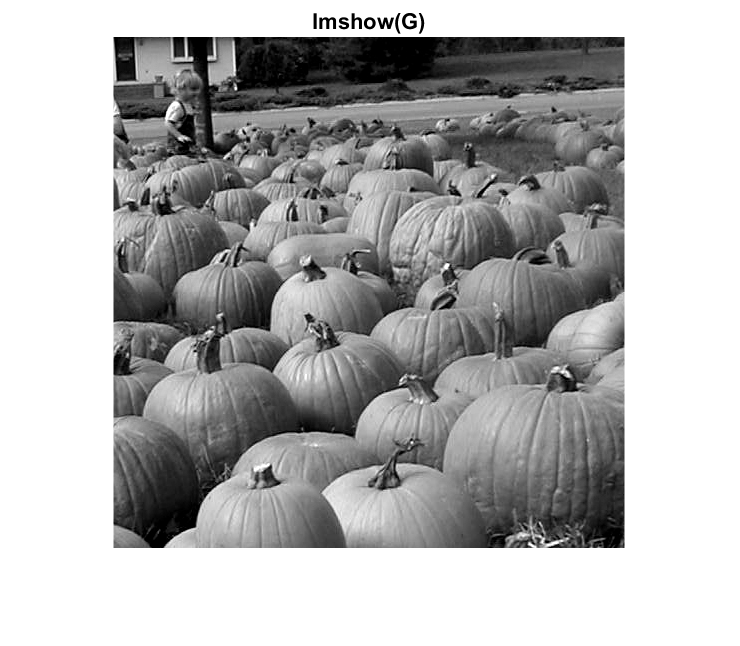

figure, imshow(G), title("Imshow(G)")

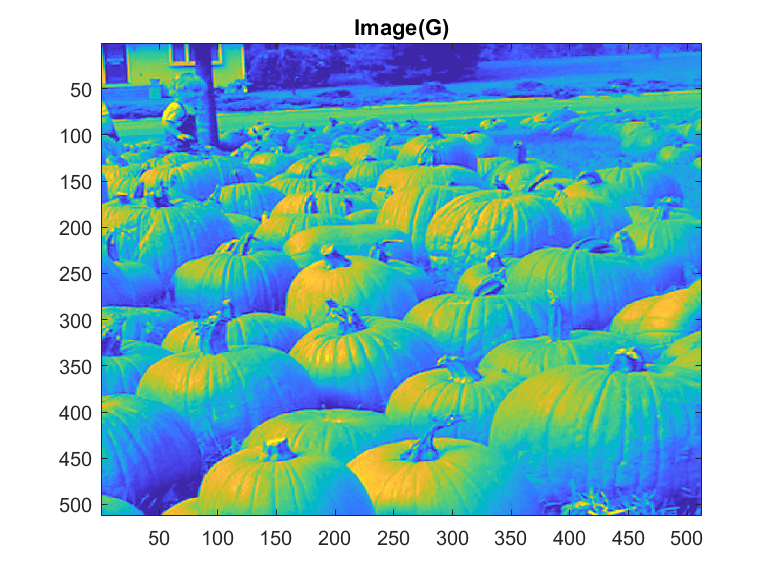

figure, image(G), title("Image(G)")

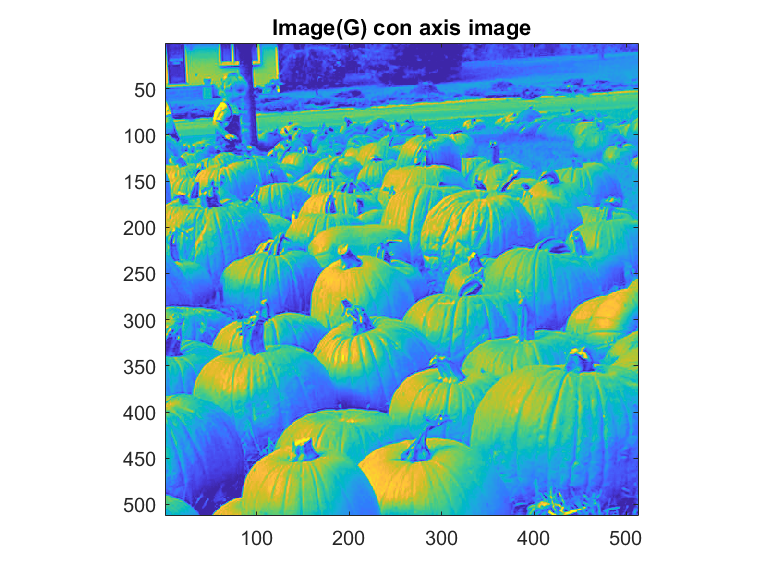

figure, image(G), title("Image(G) con axis image"), axis image 

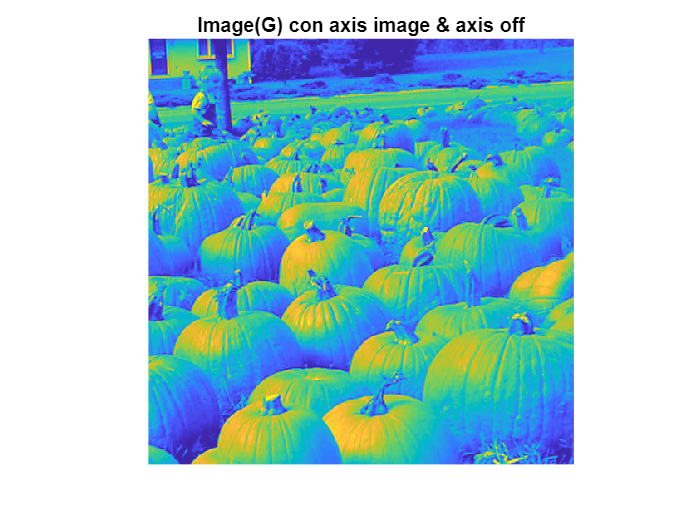

figure, image(G), title("Image(G) con axis image & axis off"), axis image, axis off

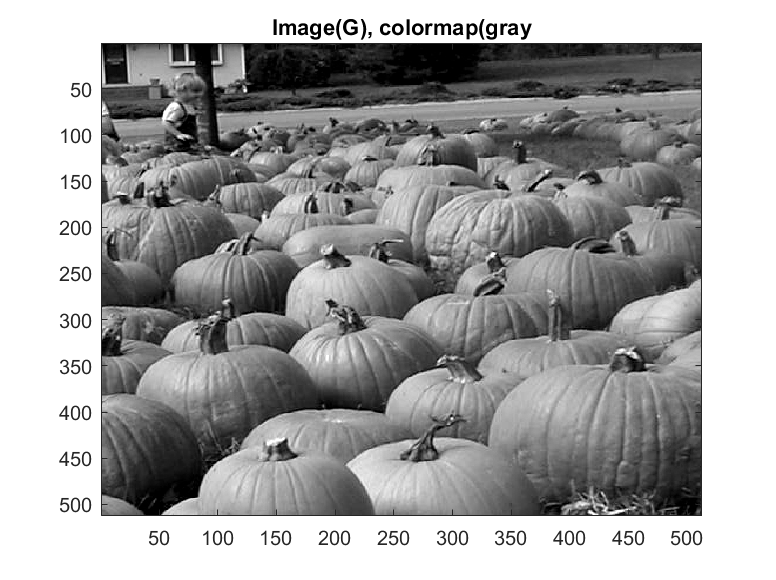

figure, image(G), colormap(gray), title("Image(G), colormap(gray")

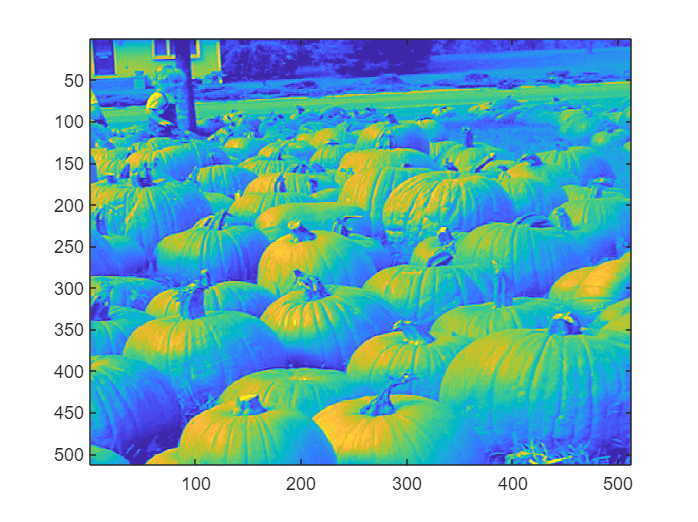

figure, imagesc(G)

### Changing format

Se haría como: 

>> G=imread("image.tif")

>>imwrite(G,"image.jpg")